**FIRST READ THE DATA SET (CSV FORMAT)**

clc %clears the command window
close all %close all windows
clear all %clears the workspace

Path = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/';
warning("off")

colaccX = 3;
colaccY = 4;
colaccZ = 5;

colgyroX = 10;
colgyroY = 11;
colgyroZ = 12;

colgravX = 21;
colgravY = 22;
colgravZ = 23;

M = 64;

% Path_Jake = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/3. Truncated/';
% warning("off")
% 
% colaccX_Jake = 1;
% colaccY_Jake = 2;
% colaccZ_Jake = 3;
% 
% colgyroX_Jake = 4;
% colgyroY_Jake = 5;
% colgyroZ_Jake = 6;
% 
% M_Jake = 32;

% Path_Disha= '/Users/mac/Desktop/FYP/Code and Data/Data Files/';
% warning("off")
% 
% colaccX_Disha = 1;
% colaccY_Disha = 2;
% colaccZ_Disha = 3;
% 
% colgyroX_Disha = 4;
% colgyroY_Disha = 5;
% colgyroZ_Disha = 6;
% 
% M_Disha = 64;

% from_watch = [-0.19387084, -0.19379486, -0.19388515, -0.19386564, -0.19385006, -0.19383197, -0.19381699, -0.19380648, -0.20589784, -0.2102094, -0.21045966, -0.20710889, -0.20339389, -0.20008567, -0.19681796, -0.19333765, -0.1897456, -0.18676169, -0.18433152, -0.18307182, -0.18229951, -0.1821173, -0.18164054, -0.1810615, -0.18071707, -0.17957868, -0.177794, -0.17534529, -0.17269532, -0.17016777, -0.16719984, -0.16417505, -0.1605712, -0.15601864, -0.15131098, -0.14699766, -0.1431294, -0.13810538, -0.13277325, -0.12750229, -0.1216712, -0.114993826, -0.10758354, -0.100177534, -0.092872545, -0.08529153, -0.078368746, -0.07143874, -0.0650919, -0.0579179, -0.049451444, -0.040897932, -0.03323373, -0.025390776, -0.01716562, -0.009370597, -0.0041047167, -0.00044135557, 0.0058974246, 0.011935623, 0.01848591, 0.025349993, 0.03684439, 0.04080732, 0.04081931, 0.04099611, 0.040770564, 0.044087294, 0.042964168, 0.042364616, 0.03954566, 0.035660118, 0.031202562, 0.025706256, 0.020928558, 0.015851356, 0.012112499, 0.009056378, 0.005311875, 0.003319371, 0.0030537166, 0.0039965757, 0.0040205843, 0.0036960756, 0.004310728, 0.0059731156, 0.0067403824, 0.008260911, 0.009360472, 0.010195538, 0.013070722, 0.016328465, 0.017644743, 0.018863743, 0.019694248, 0.01998021, 0.020469261, 0.021756055, 0.023549654, 0.025751878, 0.028074652, 0.031059636, 0.034154113, 0.037084285, 0.039715048, 0.041951258, 0.04373913, 0.045678653, 0.0480379, 0.050413515, 0.052509196, 0.05344907, 0.051809274, 0.050993122, 0.050575044, 0.05050465, 0.050782643, 0.052072607, 0.052553415, 0.051848263, 0.05080875, 0.050135337, 0.049389064, 0.048426464, 0.04783259, 0.047463484, 0.04680325, 0.045867953, 0.045120288, 0.044373102, 0.043730557, 0.043168433, 0.0433986, 0.04430251, 0.04538274, 0.046909504, 0.04908603, 0.051874798, 0.055326387, 0.05966767, 0.064982146, 0.07145861, 0.07912201, 0.08795332, 0.09818664, 0.110175565, 0.12395939, 0.13932054, 0.15553185, 0.17235677, 0.18968646, 0.20711853, 0.22464812, 0.2412792, 0.2567108, 0.27130407, 0.28527635, 0.2983363, 0.30969456, 0.31881273, 0.32594207, 0.33094674, 0.3337151, 0.33464044, 0.33347017, 0.3297499, 0.32376432, 0.31480038, 0.30293474, 0.28809714, 0.27025607, 0.24880134, 0.22352687, 0.19387743, 0.16035298, 0.122739464, 0.08153963, 0.03540872, -0.015996253, -0.07170749, -0.1304853, -0.19217822, -0.25608644, -0.31987557, -0.3833753, -0.44864193, -0.5135826, -0.575994, -0.6379096, -0.70047706, -0.7611466, -0.81511885, -0.8609793, -0.89262444, -0.89262444, -0.90932953, -0.897798, -0.846042, -0.7521626, -0.6276877, -0.4849994, -0.3477979, -0.2221788, -0.085100174, 0.051403034, 0.1492327, 0.2148057, 0.26262072, 0.3036465, 0.32911152, 0.3384094, 0.34068662, 0.3547854, 0.37299082, 0.39657393, 0.41874832, 0.4353913, 0.44583037, 0.45326963, 0.45953077, 0.46493706, 0.4711032, 0.47676528, 0.48372513, 0.49007583, 0.49452817, 0.49841276, 0.5026785, 0.5068774, 0.51074344, 0.51393586, 0.51642394, 0.5189322, 0.52037716, 0.5206296, 0.5200964, 0.5196318, 0.51884776, 0.5174888, 0.5160119, 0.51513416, 0.51474464, 0.51461196, 0.5156105, 0.5171813, 0.5189241, 0.5203555, 0.52219146, 0.52334076, 0.5239256, 0.52382576, 0.52341104, 0.52295953, 0.5224386];
% plot(from_watch)
% hold off
% 
% from_watch1 = [-1.3081604, -1.397996, -1.489778, -1.6401266, -1.7635016, -1.8448827, -1.8314428, -2.107822, -2.1527317, -2.1869662, -2.2991076, -2.3273022, -2.3959315, -2.508562, -2.5684023, -2.6794636, -2.7508047, -2.8909245, -3.0333326, -3.149107, -3.221309, -3.3207505, -3.3979075, -3.4531736, -3.5025418, -3.5531583, -3.544931, -3.6022046, -3.578049, -3.5563753, -3.5540655, -3.548833, -3.466596, -3.4084306, -3.393359, -3.3250656, -3.3194451, -3.3539364, -3.2985182, -3.4239805, -3.5153728, -3.4561563, -3.49672, -3.4840453, -3.4777145, -3.5213525, -3.516823, -3.6123092, -3.6874852, -3.70654, -3.803619, -3.7448838, -3.7507148, -3.528035, -3.178995, -2.5232334, -1.5000359, -0.09207588, 1.0658412, 1.6835771, 1.6835771, 2.2006655, 2.4078395, 2.780607, 4.0272202, 5.8540463, 7.101985, 8.165104, 7.8929796, 7.698376, 6.858272, 6.3681216, 5.963617, 5.1967497, 4.330945, 3.461364, 2.632907, 1.9160812, 1.425607, 1.048671, 0.518041, -0.25262707, -0.30585873, -0.34204417, -0.22092547, -0.08173242, -0.090268515, -0.09522267, -0.083641246, -0.07008975, -0.072296575, -0.07475907, -0.051614065, -0.019352004, -0.0043866346, 0.03250587, 0.02202247, 0.013929788, 0.027888881, 0.026871152, 0.052061994, 0.03758159, 0.017616136, -0.004231504, -0.0122854365, -0.02549871, -0.020243628, -0.041785, -0.04993508, -0.069505185, -0.06695108, -0.07498504, -0.07057031, -0.05957772, -0.056056216, -0.03540141, -0.029146042, -0.028494898, -0.012871198, 0.00015152525];
% plot(from_watch1)
% hold on
% from_watch2 = [-1.0435635, -1.2961049, -2.180014, -1.5336996, -1.6604838, -2.0677176, -1.9483427, -1.8140136, -2.1283565, -2.24126, -2.3794582, -2.6219947, -2.7556589, -2.7513509, -2.7691526, -2.8098905, -2.8043094, -2.7567518, -2.7961066, -2.8899186, -2.9321644, -2.9930577, -3.029486, -3.0869787, -3.1563282, -3.198729, -3.2258759, -3.2931294, -3.3316767, -3.3635561, -3.4488199, -3.5403137, -3.5960023, -3.5948458, -3.5491652, -3.4418163, -3.4454386, -3.335148, -3.172156, -3.0395408, -2.9867723, -2.9516902, -2.9266324, -3.001927, -2.9576483, -3.0105603, -2.9587328, -3.0730803, -3.0509148, -3.037699, -2.8935244, -2.953631, -2.9420207, -2.964812, -3.1652515, -3.184412, -3.0647588, -2.648089, -1.7503145, -0.6314247, -0.6314247, 0.6441908, 1.7424552, 2.5606215, 3.1025906, 3.9817913, 5.259962, 6.8038917, 8.058766, 8.922511, 8.449363, 7.9802284, 7.3520055, 6.8177686, 6.115373, 5.3478255, 4.5689654, 3.7470198, 2.9288127, 2.2042077, 1.599834, 1.1141621, 0.7026965, 0.43263876, 0.15151615, -0.023623979, -0.12121378, -0.21107057, -0.20033737, -0.232364, -0.26525712, -0.32880053, -0.34436354, -0.5331466, -0.5402627, -0.5236129, -0.50692886, -0.43587095, -0.38394675, -0.3348366, -0.2754292, -0.24905658, -0.19244587, -0.1455777, -0.10753166, -0.086578704, -0.06003671, -0.038403325, -0.0026622368, 0.031037137, 0.043251727, 0.043555457, 0.03134127, 0.032961138, -0.022828225, 0.012304728, 0.00023941044, 0.024163652, 0.016836496, -0.0008925665];
% plot(from_watch2)
% hold off


## **Forehands (my data)**

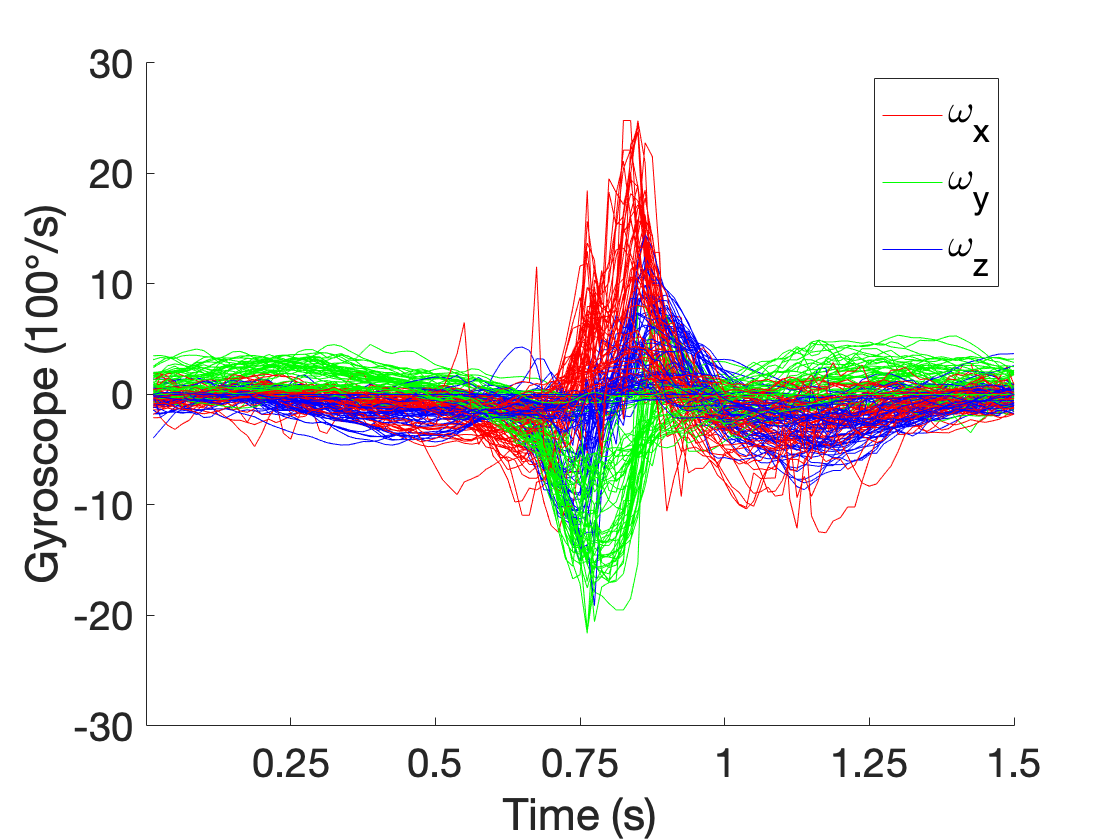

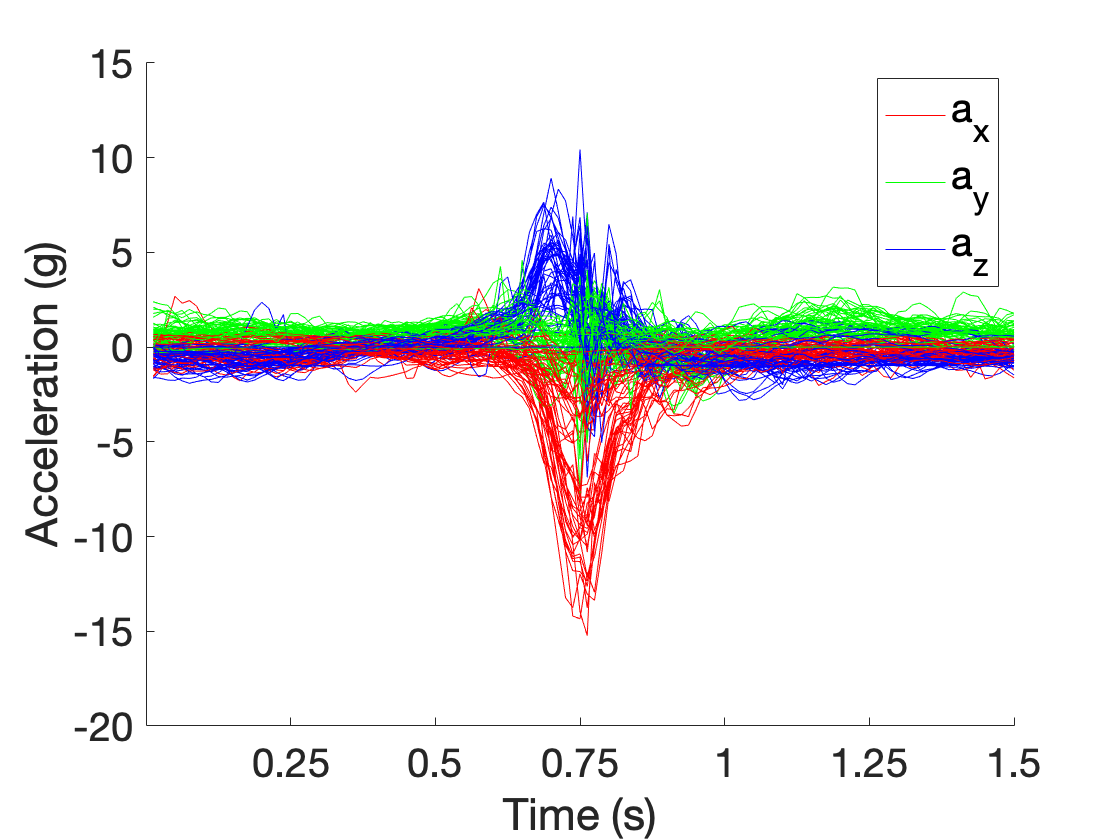

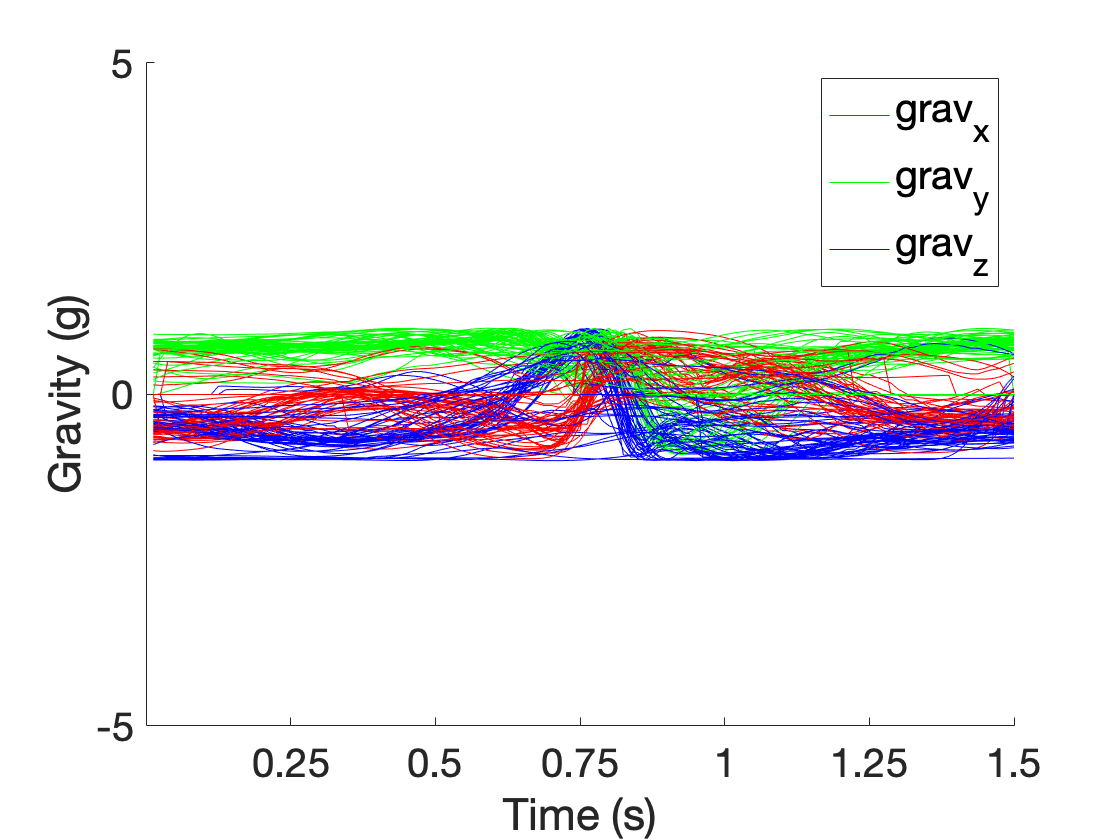

Filename1 = string(Path) + 'Player 17/M.Me.Fd.17.1.csv';
Filename2 = string(Path) + 'Player 17/M.Me.Fd.17.2.csv';
Filename3 = string(Path) + 'Player 17/M.Me.Fd.17.3.csv';
Filename4 = string(Path) + 'Player 16/M.E.Fd.16.csv';
Filename5 = string(Path) + 'Player 20/F.B.Fd.20.1.csv';
Filename6 = string(Path) + 'Player 20/F.B.Fd.20.2.csv';
Filename7 = string(Path) + 'Player 21/F.B.Fd.21.1.csv';
Filename8 = string(Path) + 'Player 21/F.B.Fd.21.2.csv';
Filename9 = string(Path) + 'Player 22/M.B.Fd.22.1.csv';
Filename10 = string(Path) + 'Player 22/M.B.Fd.22.2.csv';
Filename11 = string(Path) + 'Player 23/M.Me.Fd.23.1.csv';
Filename12 = string(Path) + 'Player 23/M.Me.Fd.23.2.csv';
Filename13 = string(Path) + 'Player 26/F.B.Fd.26.1.csv';
Filename14 = string(Path) + 'Player 26/F.B.Fd.26.2.csv';
Filename15 = string(Path) + 'Player 27/F.B.Fd.27.1.csv';
Filename16 = string(Path) + 'Player 27/F.B.Fd.27.2.csv';

files_fd = [Filename1, Filename2, Filename3, Filename4, Filename5, Filename6, Filename7, Filename8,Filename9,Filename10,Filename11,Filename12,Filename13,Filename14,Filename15,Filename16];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 32.2824

## Forehand (Benji's data)

% Filename1_Jake = string(Path_Jake) + 'ft_1(10).csv';
% Filename2_Jake = string(Path_Jake) + 'ft_2(10).csv';
% Filename3_Jake = string(Path_Jake) + 'ft_3(10).csv';
% Filename4_Jake = string(Path_Jake) + 'ft_4(10).csv';
% Filename5_Jake = string(Path_Jake) + 'ft_5(10).csv';
% Filename6_Jake = string(Path_Jake) + 'ft_6(10).csv';
% 
% files_fd_Jake = [Filename1_Jake, Filename2_Jake, Filename3_Jake, Filename4_Jake, Filename5_Jake, Filename6_Jake];
% 
% [AllfJGyroX,AllfJGyroY,AllfJGyroZ,AllfJAccelX,AllfJAccelY,AllfJAccelZ] = Compile_trial(files_fd_Jake, M_Jake, colaccX_Jake,colaccY_Jake,colaccZ_Jake,colgyroX_Jake,colgyroY_Jake,colgyroZ_Jake);
% [faJMax,faJMin,faJMean,faJStd,faJArea,fgJMax,fgJMin,fgJMean,fgJStd,fgJArea] = MaxMin_trial(AllfJGyroX,AllfJGyroY,AllfJGyroZ,AllfJAccelX,AllfJAccelY,AllfJAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllfJGyroY, AllfJGyroZ);

## Forehand (Disha's data)

% Filename1= string(Path_Disha) + '00049_CalInertialAndMag.csv';% Disha
% Filename2= string(Path_Disha) + '00060_CalInertialAndMag.csv';% Hannah
% Filename3= string(Path_Disha) + '00065_CalInertialAndMag.csv';% Katarina
% Filename4= string(Path_Disha) + '00068_CalInertialAndMag.csv';% Thomas
% 
% files_fd_Disha = [Filename1, Filename2, Filename3, Filename4];
% 
% [AllfDGyroX,AllfDGyroY,AllfDGyroZ,AllfDAccelX,AllfDAccelY,AllfDAccelZ] = Compile_trial(files_fd_Disha, M_Disha, colaccX_Disha,colaccY_Disha,colaccZ_Disha,colgyroX_Disha,colgyroY_Disha,colgyroZ_Disha);
% [faDMax,faDMin,faDMean,faDStd,faDArea,fgDMax,fgDMin,fgDMean,fgDStd,fgDArea] = MaxMin_trial(AllfDGyroX,AllfDGyroY,AllfDGyroZ,AllfDAccelX,AllfDAccelY,AllfDAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllfDGyroY, AllfDGyroZ);

## Forehand NO FOLLOW-THROUGH

% Filename1= string(Path) + 'No_followthourgh_trial/No_followthrough.1.csv';% Disha
% Filename2= string(Path) + 'No_followthourgh_trial/No_followthrough.2.csv';% Hannah
% Filename3= string(Path) + 'No_followthourgh_trial/No_followthrough.3.csv';% Katarina
% Filename4= string(Path) + 'No_followthourgh_trial/No_followthrough.4.csv';% Thomas
% 
% files_fd_No_followthrough = [Filename1, Filename2, Filename3, Filename4];
% 
% [AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd_No_followthrough,16, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);
% [faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
% [RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

## Forehand Misses

% Filename1= string(Path) + 'Misses/Misses.1.csv';
% Filename2= string(Path) + 'Misses/Misses.2.csv';
% Filename3= string(Path) + 'Misses/Misses.3.csv';
% Filename4= string(Path) + 'Misses/Misses.4.csv';
% 
% files_fd_Misses = [Filename1, Filename2, Filename3, Filename4];
% 
% [AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd_Misses,32, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);
% [faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
% [RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

## **Backhands (my data)**

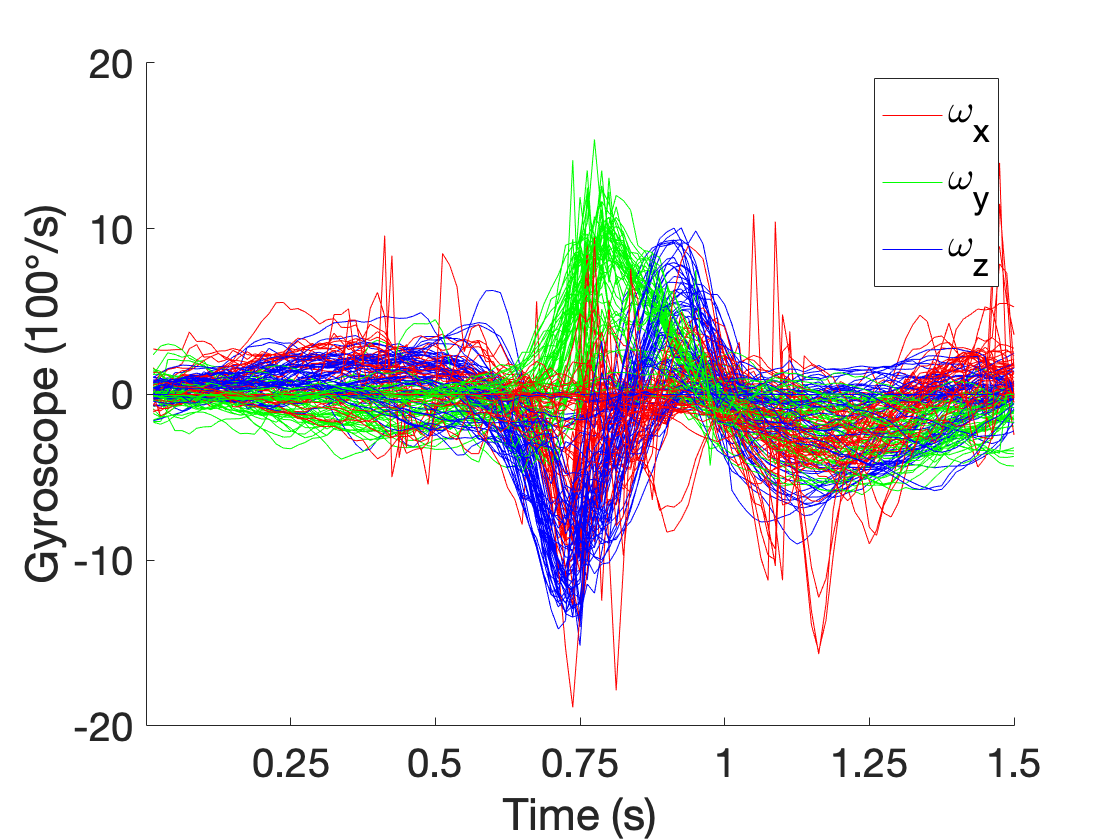

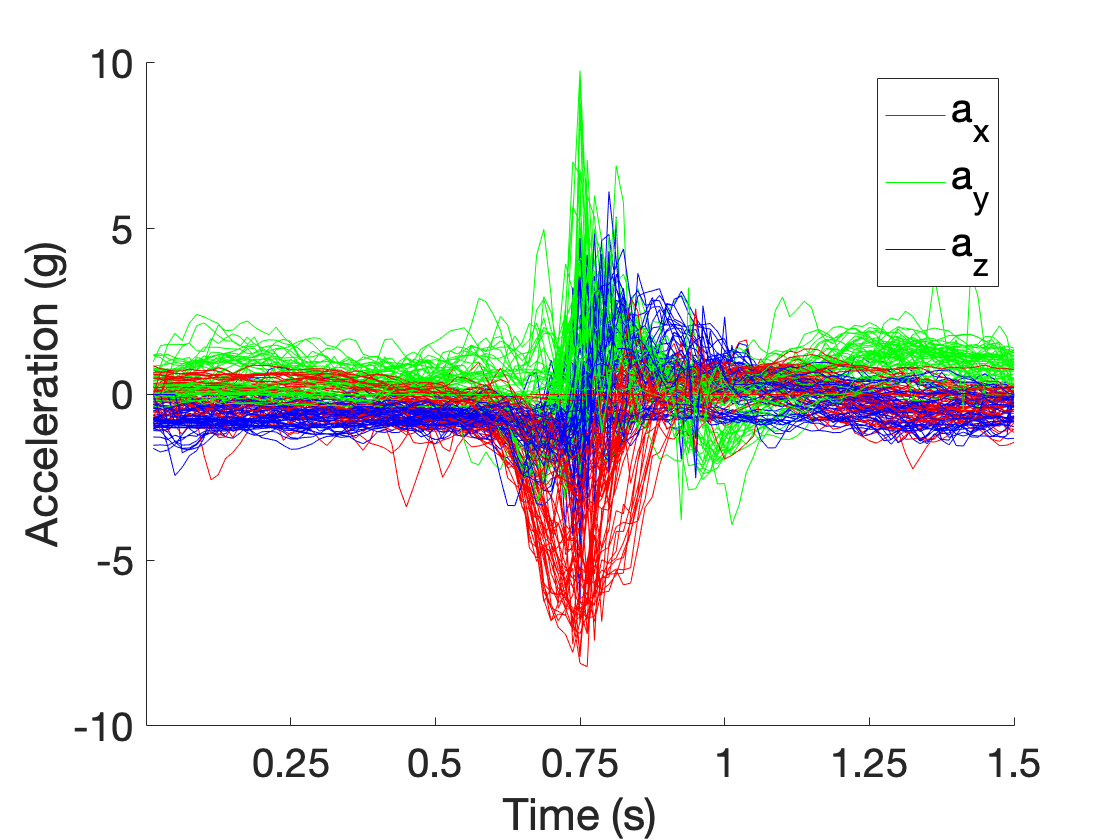

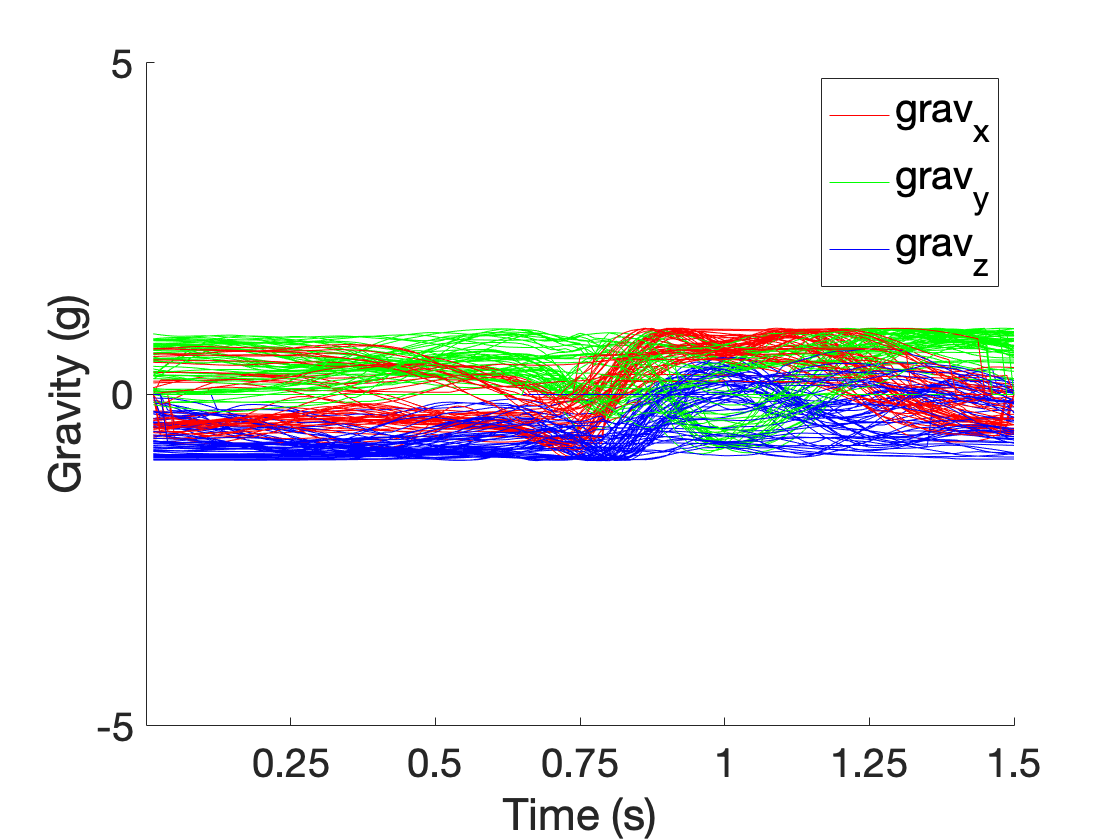

Filename17 = string(Path) + 'Player 17/M.Me.Bd.17.1.csv';
Filename18 = string(Path) + 'Player 17/M.Me.Bd.17.2.csv';
Filename19 = string(Path) + 'Player 17/M.Me.Bd.17.3.csv';
Filename20 = string(Path) + 'Player 16/M.E.Bd.16.csv';
Filename21 = string(Path) + 'Player 20/F.B.Bd.20.1.csv';
Filename22 = string(Path) + 'Player 20/F.B.Bd.20.2.csv';
Filename23 = string(Path) + 'Player 21/F.B.Bd.21.1.csv';
Filename24 = string(Path) + 'Player 21/F.B.Bd.21.2.csv';
Filename25 = string(Path) + 'Player 22/M.B.Bd.22.1.csv';
Filename26 = string(Path) + 'Player 22/M.B.Bd.22.2.csv';
Filename27 = string(Path) + 'Player 23/M.Me.Bd.23.1.csv';
Filename28 = string(Path) + 'Player 23/M.Me.Bd.23.2.csv';
Filename29 = string(Path) + 'Player 26/F.B.Bd.26.1.csv';
Filename30 = string(Path) + 'Player 26/F.B.Bd.26.2.csv';
Filename31 = string(Path) + 'Player 27/F.B.Bd.27.1.csv';
Filename32 = string(Path) + 'Player 27/F.B.Bd.27.2.csv';



files_bd = [Filename17, Filename18, Filename19, Filename20,Filename21,Filename22,Filename23,Filename24,Filename25,Filename26,Filename27,Filename28,Filename29,Filename30,Filename31,Filename32];

[AllbGyroX,AllbGyroY,AllbGyroZ,AllbAccelX,AllbAccelY,AllbAccelZ,AllbGravX,AllbGravY,AllbGravZ] = Compile_trial(files_bd, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[baMax,baMin,baMean,baStd,baArea,bgMax,bgMin,bgMean,bgStd,bgArea,bgravMax,bgravMin,bgravMean,bgravStd,bgravArea] = MaxMin_trial(AllbGyroX,AllbGyroY,AllbGyroZ,AllbAccelX,AllbAccelY,AllbAccelZ,AllbGravX,AllbGravY,AllbGravZ);
[RacketSpeedAverage] = RacketSpeed(AllbGyroY, AllbGyroZ);

RacketSpeedAverage = 30.2367

## Backhand (Benji's data)

% Filename7_Jake = string(Path_Jake) + 'bt_1(10).csv';
% Filename8_Jake = string(Path_Jake) + 'bt_2(10).csv';
% Filename9_Jake = string(Path_Jake) + 'bt_3(10).csv';
% Filename10_Jake = string(Path_Jake) + 'bt_4(10).csv';
% Filename11_Jake = string(Path_Jake) + 'bt_5(10).csv';
% 
% files_bd_Jake = [Filename7_Jake, Filename8_Jake, Filename9_Jake, Filename10_Jake, Filename11_Jake];
% 
% [AllbJGyroX,AllbJGyroY,AllbJGyroZ,AllbJAccelX,AllbJAccelY,AllbJAccelZ] = Compile_trial(files_bd_Jake,M_Jake, colaccX_Jake,colaccY_Jake,colaccZ_Jake,colgyroX_Jake,colgyroY_Jake,colgyroZ_Jake);
% [baJMax,baJMin,baJMean,baJStd,baJArea,bgJMax,bgJMin,bgJMean,bgJStd,bgJArea] = MaxMin_trial(AllbJGyroX,AllbJGyroY,AllbJGyroZ,AllbJAccelX,AllbJAccelY,AllbJAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllbJGyroY, AllbJGyroZ);

## Backhand (Disha's data)

% Filename1= string(Path_Disha) + '00050_CalInertialAndMag.csv';% Disha
% Filename2= string(Path_Disha) + '00050_CalInertialAndMag.csv';% Disha
% Filename3= string(Path_Disha) + '00066_CalInertialAndMag.csv';% Katarina
% Filename4= string(Path_Disha) + '00069_CalInertialAndMag.csv';% Thomas
% 
% files_bd_Disha = [Filename1, Filename2, Filename3, Filename4];
% 
% [AllbDGyroX,AllbDGyroY,AllbDGyroZ,AllbDAccelX,AllbDAccelY,AllbDAccelZ] = Compile_trial(files_bd_Disha, M_Disha, colaccX_Disha,colaccY_Disha,colaccZ_Disha,colgyroX_Disha,colgyroY_Disha,colgyroZ_Disha);
% [baDMax,baDMin,baDMean,baDStd,baDArea,bgDMax,bgDMin,bgDMean,bgDStd,bgDArea] = MaxMin_trial(AllbDGyroX,AllbDGyroY,AllbDGyroZ,AllbDAccelX,AllbDAccelY,AllbDAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllbDGyroY, AllbDGyroZ);

## Serves (My data)

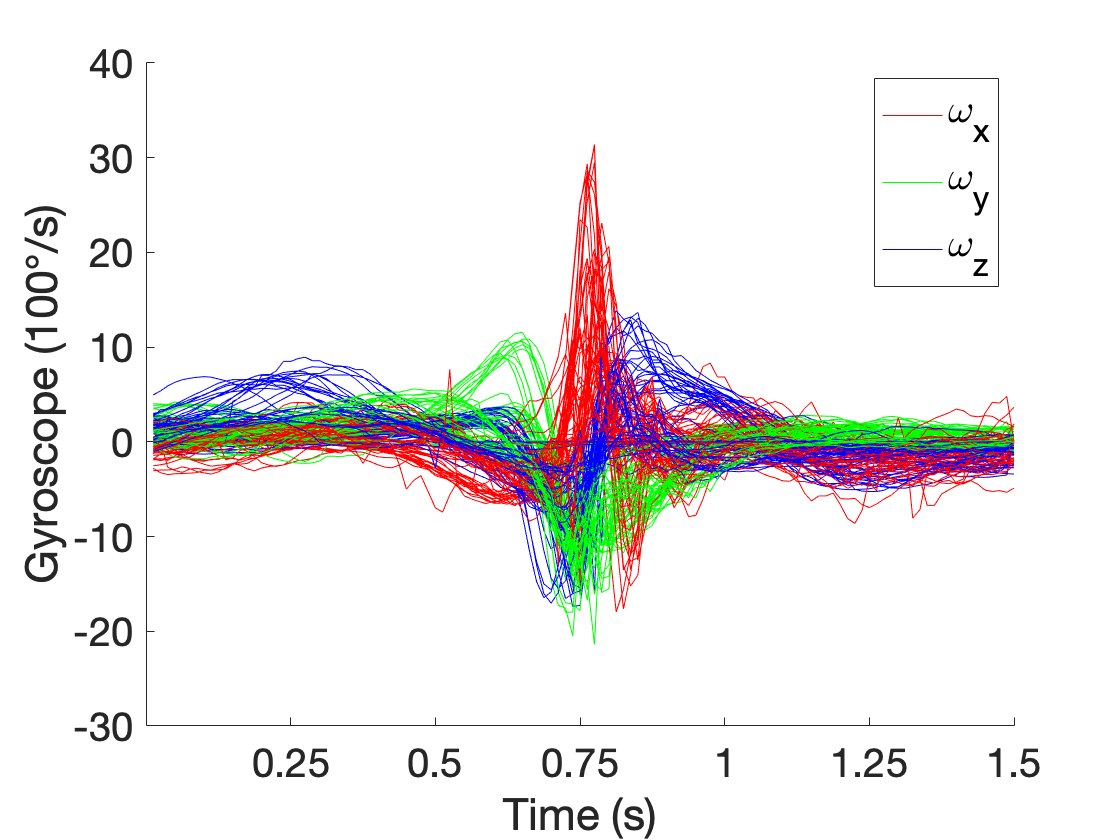

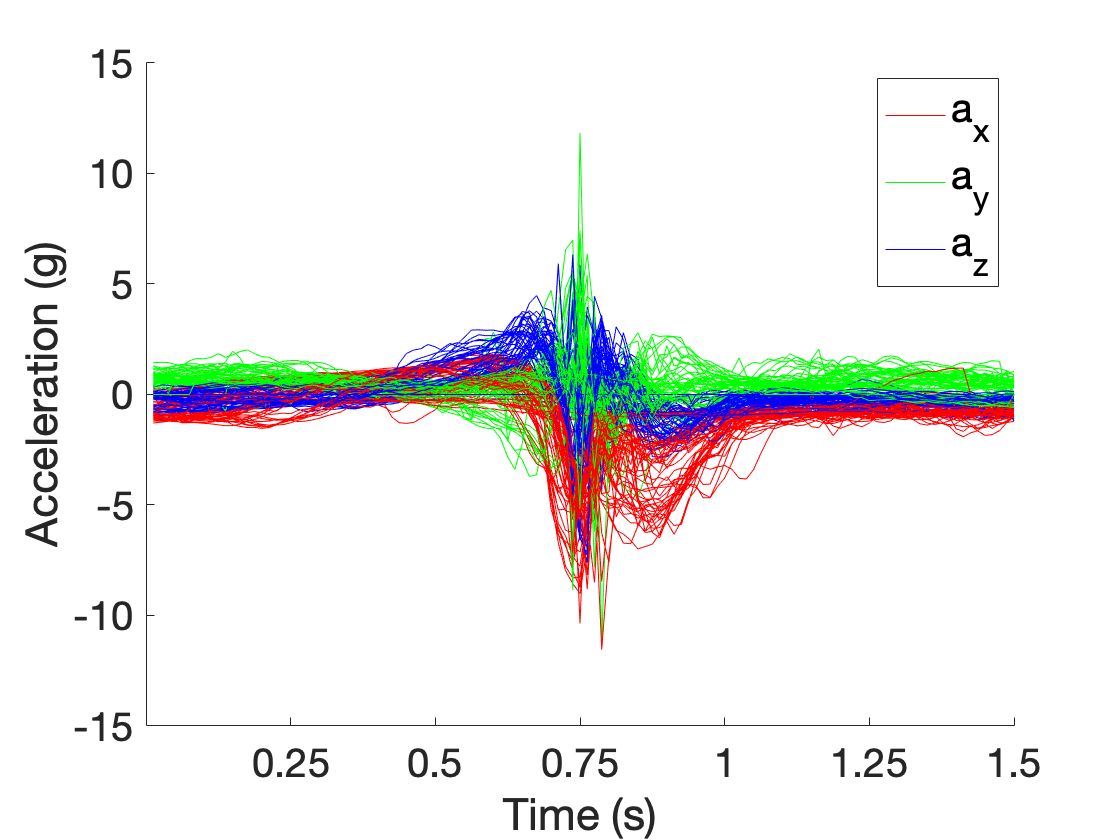

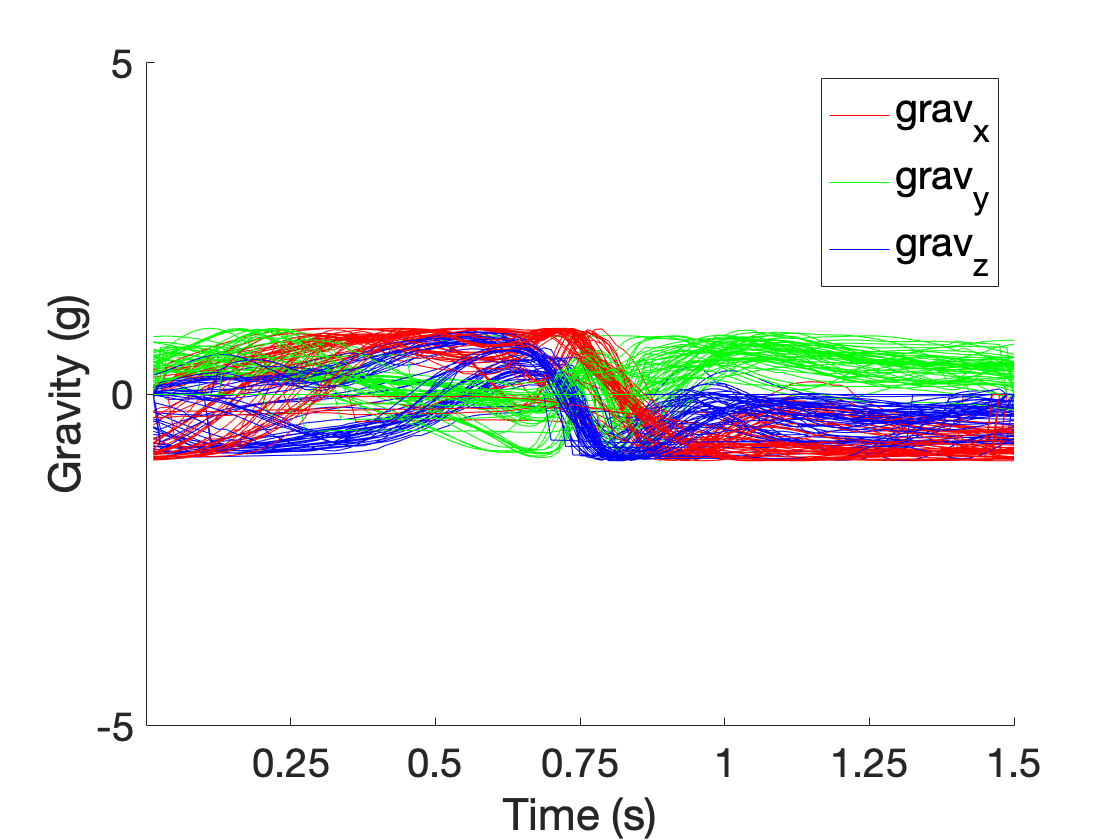

Filename33 = string(Path) + 'Player 17/M.Me.S.17.1.csv';
Filename34 = string(Path) + 'Player 17/M.Me.S.17.2.csv';
Filename35 = string(Path) + 'Player 16/M.E.S.16.csv';
Filename36 = string(Path) + 'Player 15/M.E.S.15.csv';
Filename37 = string(Path) + 'Player 21/F.B.S.21.1.csv';
Filename38 = string(Path) + 'Player 21/F.B.S.21.2.csv';
Filename39 = string(Path) + 'Player 21/F.B.S.21.3.csv';
Filename40 = string(Path) + 'Player 22/M.B.S.22.1.csv';
Filename41 = string(Path) + 'Player 22/M.B.S.22.2.csv';
Filename42 = string(Path) + 'Player 24/F.E.S.24.csv';
Filename43 = string(Path) + 'Player 25/F.E.S.25.csv';
Filename44 = string(Path) + 'Player 26/F.B.S.26.1.csv';
Filename45 = string(Path) + 'Player 26/F.B.S.26.2.csv';

files_s = [Filename33, Filename34, Filename35, Filename36,Filename37,Filename38,Filename39,Filename40,Filename41,Filename42,Filename43,Filename44,Filename45];

[AllsGyroX,AllsGyroY,AllsGyroZ,AllsAccelX,AllsAccelY,AllsAccelZ,AllsGravX,AllsGravY,AllsGravZ] = Compile_trial(files_s, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[saMax,saMin,saMean,saStd,saArea,sgMax,sgMin,sgMean,sgStd,sgArea,sgravMax,sgravMin,sgravMean,sgravStd,sgravArea] = MaxMin_trial(AllsGyroX,AllsGyroY,AllsGyroZ,AllsAccelX,AllsAccelY,AllsAccelZ,AllsGravX,AllsGravY,AllsGravZ);
[RacketSpeedAverage] = RacketSpeed(AllsGyroY, AllsGyroZ);

RacketSpeedAverage = 35.2713

## Serves (Benji's data)

% Filename12_Jake = string(Path_Jake) + 'sv_1(7).csv';
% Filename13_Jake = string(Path_Jake) + 'sv_2(7).csv';
% Filename14_Jake = string(Path_Jake) + 'sv_3(7).csv';
% Filename15_Jake = string(Path_Jake) + 'sv_4(10).csv';
% Filename16_Jake = string(Path_Jake) + 'sv_5(5).csv';
% Filename17_Jake = string(Path_Jake) + 'sv_5(5).csv';
% 
% files_sv_Jake = [Filename12_Jake, Filename13_Jake, Filename14_Jake, Filename15_Jake, Filename16_Jake];
% 
% [AllsvJGyroX,AllsvJGyroY,AllsvJGyroZ,AllsvJAccelX,AllsvJAccelY,AllsvJAccelZ] = Compile_trial(files_sv_Jake,M_Jake, colaccX_Jake,colaccY_Jake,colaccZ_Jake,colgyroX_Jake,colgyroY_Jake,colgyroZ_Jake);
% [svaJMax,svaJMin,svaJMean,svaJStd,svaJArea,svgJMax,svgJMin,svgJMean,svgJStd,svgJArea] = MaxMin_trial(AllsvJGyroX,AllsvJGyroY,AllsvJGyroZ,AllsvJAccelX,AllsvJAccelY,AllsvJAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllsvJGyroY, AllsvJGyroZ);

## Serve (Disha's data)

% Filename1= string(Path_Disha) + '00057_CalInertialAndMag.csv';% Disha
% Filename2= string(Path_Disha) + '00057_CalInertialAndMag.csv';% Disha
% Filename3= string(Path_Disha) + '00067_CalInertialAndMag.csv';% Katarina and Hannah
% Filename4= string(Path_Disha) + '00070_CalInertialAndMag.csv';% Thomas
% 
% files_s_Disha = [Filename1, Filename2, Filename3, Filename4];
% 
% [AllsDGyroX,AllsDGyroY,AllsDGyroZ,AllsDAccelX,AllsDAccelY,AllsDAccelZ] = Compile_trial(files_s_Disha, M_Disha, colaccX_Disha,colaccY_Disha,colaccZ_Disha,colgyroX_Disha,colgyroY_Disha,colgyroZ_Disha);
% [saDMax,saDMin,saDMean,saDStd,saDArea,sgDMax,sgDMin,sgDMean,sgDStd,sgDArea] = MaxMin_trial(AllsDGyroX,AllsDGyroY,AllsDGyroZ,AllsDAccelX,AllsDAccelY,AllsDAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllsDGyroY, AllsDGyroZ);

## Forehand Volleys (My data)

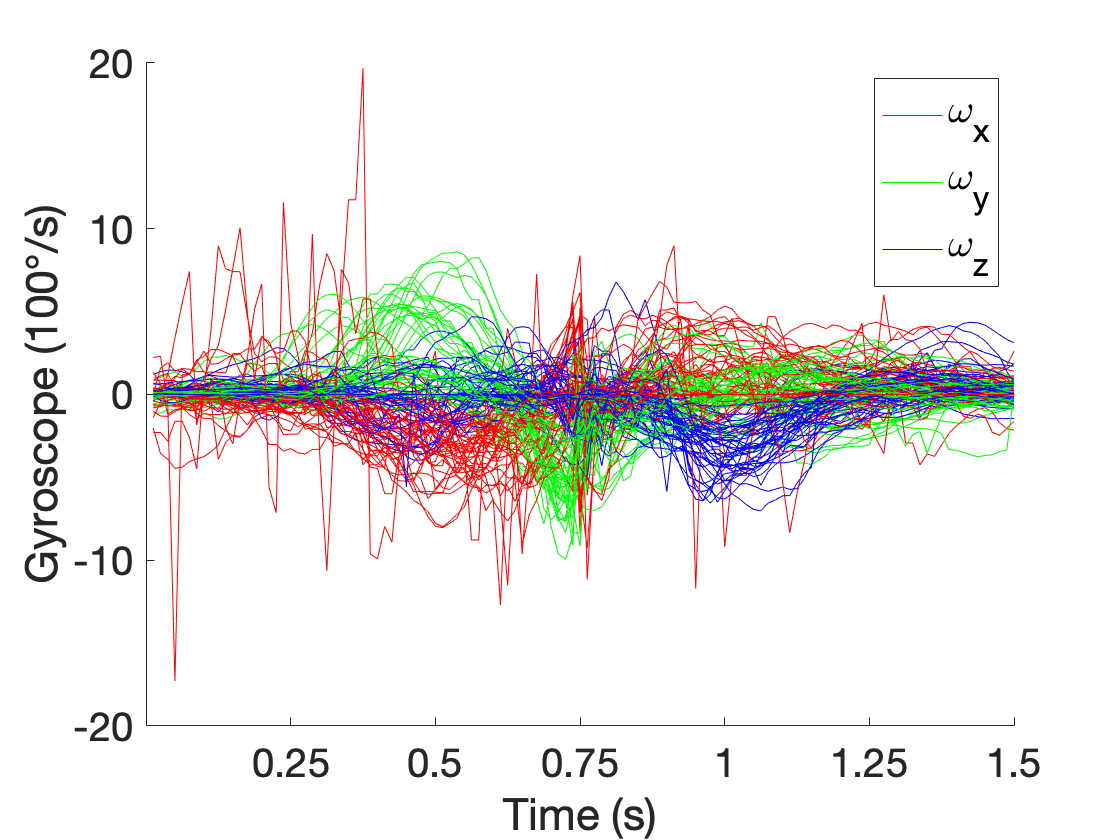

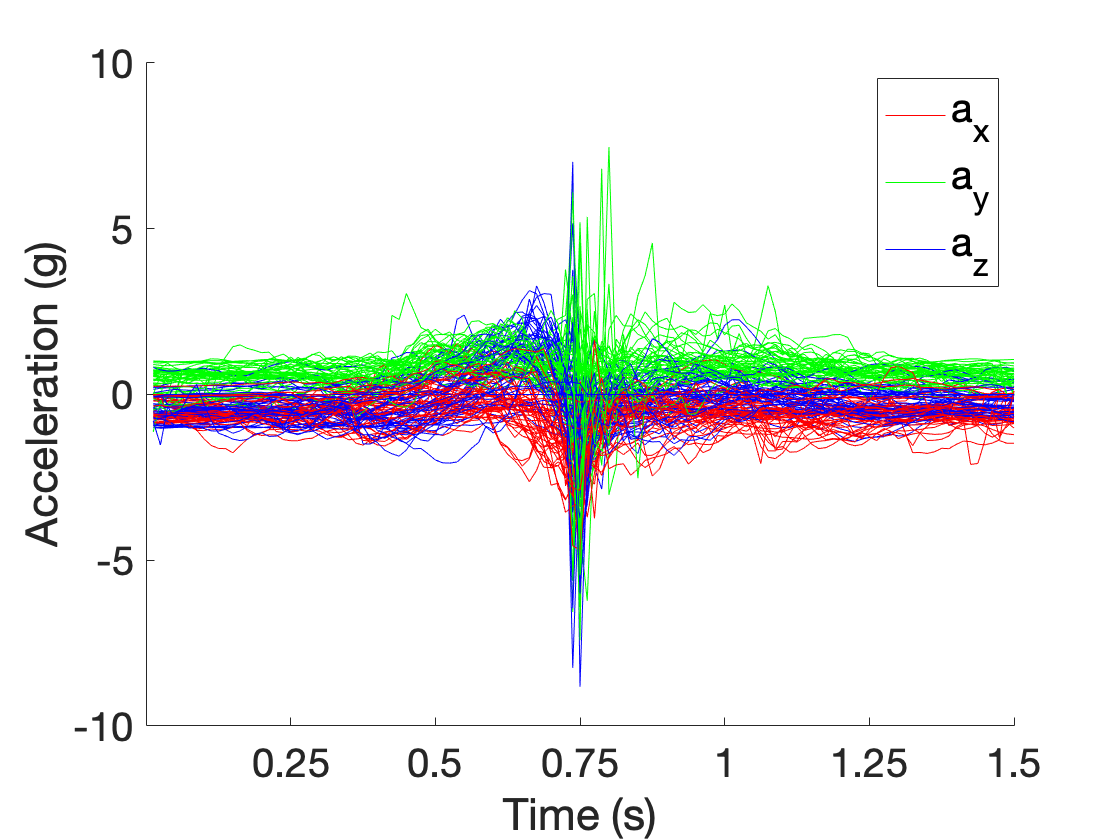

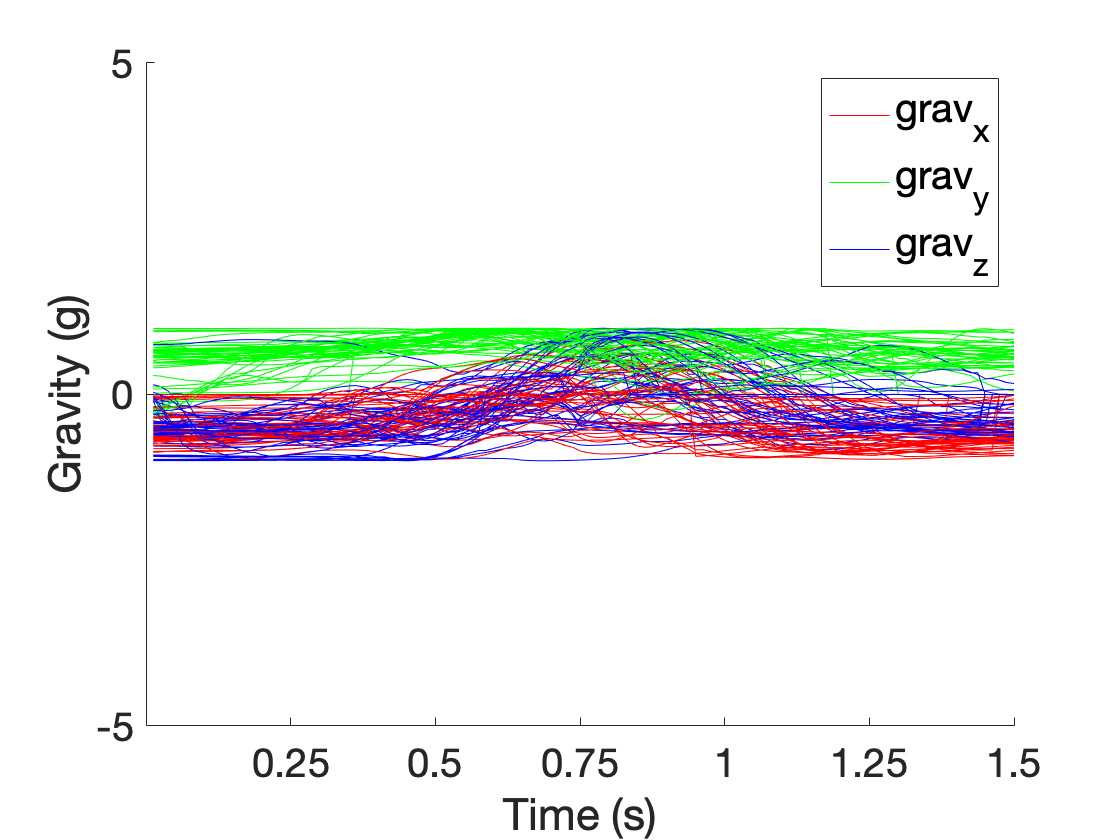

% Change variable names
Filename46 = string(Path) + 'Player 23/M.Me.FdV.23.1.csv';
Filename47 = string(Path) + 'Player 23/M.Me.FdV.23.2.csv';
Filename51 = string(Path) + 'Player 23/M.Me.FdV.23.3.csv';
Filename48 = string(Path) + 'Player 21/F.B.FdV.21.1.csv';
Filename49 = string(Path) + 'Player 21/F.B.FdV.21.2.csv';
Filename50 = string(Path) + 'Player 21/F.B.FdV.21.2.csv';
Filename52 = string(Path) + 'Player 26/F.B.FdV.26.1.csv';
Filename53 = string(Path) + 'Player 26/F.B.FdV.26.2.csv';
Filename54 = string(Path) + 'Player 27/F.B.FdV.27.1.csv';
Filename55 = string(Path) + 'Player 27/F.B.FdV.27.2.csv';
Filename56 = string(Path) + 'Player 24/F.E.FdV.24.csv';
Filename57 = string(Path) + 'Player 25/F.E.FdV.25.csv';

files_fv = [Filename46, Filename47, Filename48, Filename49,Filename50,Filename51,Filename52,Filename53,Filename54,Filename55,Filename56,Filename57];

[AllfvGyroX,AllfvGyroY,AllfvGyroZ,AllfvAccelX,AllfvAccelY,AllfvAccelZ,AllfvGravX,AllfvGravY,AllfvGravZ] = Compile_trial(files_fv, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[fvaMax,fvaMin,fvaMean,fvaStd,fvaArea,fvgMax,fvgMin,fvgMean,fvgStd,fvgArea,fvgravMax,fvgravMin,fvgravMean,fvgravStd,fvgravArea] = MaxMin_trial(AllfvGyroX,AllfvGyroY,AllfvGyroZ,AllfvAccelX,AllfvAccelY,AllfvAccelZ,AllfvGravX,AllfvGravY,AllfvGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfvGyroY, AllfvGyroZ);

RacketSpeedAverage = 16.5473

## Forehand Volleys (Benji's data)

% Filename18_Jake = string(Path_Jake) + 'fv_1(10).csv';
% Filename19_Jake = string(Path_Jake) + 'fv_2(10).csv';
% Filename20_Jake = string(Path_Jake) + 'fv_4(10).csv';
% Filename21_Jake = string(Path_Jake) + 'fv_5(10).csv';
% 
% files_fv_Jake = [Filename18_Jake, Filename19_Jake, Filename20_Jake, Filename21_Jake];
% 
% [AllfvJGyroX,AllfvJGyroY,AllfvJGyroZ,AllfvJAccelX,AllfvJAccelY,AllfvJAccelZ] = Compile_trial(files_fv_Jake,M_Jake, colaccX_Jake,colaccY_Jake,colaccZ_Jake,colgyroX_Jake,colgyroY_Jake,colgyroZ_Jake);
% [fvaJMax,fvaJMin,fvaJMean,fvaJStd,fvaJArea,fvgJMax,fvgJMin,fvgJMean,fvgJStd,fvgJArea] = MaxMin_trial(AllfvJGyroX,AllfvJGyroY,AllfvJGyroZ,AllfvJAccelX,AllfvJAccelY,AllfvJAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllfvJGyroY, AllfvJGyroZ);

## Forehand Volley (Disha's data)

% Filename1= string(Path_Disha) + '00858_CalInertialAndMag.csv';% Disha
% Filename2= string(Path_Disha) + '00860_CalInertialAndMag.csv';% Belen
% 
% files_fv_Disha = [Filename1, Filename2];
% 
% [AllfvDGyroX,AllfvDGyroY,AllfvDGyroZ,AllfvDAccelX,AllfvDAccelY,AllfvDAccelZ] = Compile_trial(files_fv_Disha, 32, colaccX_Disha,colaccY_Disha,colaccZ_Disha,colgyroX_Disha,colgyroY_Disha,colgyroZ_Disha);
% [fvaDMax,fvaDMin,fvaDMean,fvaDStd,fvaDArea,fvgDMax,fvgDMin,fvgDMean,fvgDStd,fvgDArea] = MaxMin_trial(AllfvDGyroX,AllfvDGyroY,AllfvDGyroZ,AllfvDAccelX,AllfvDAccelY,AllfvDAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllfvDGyroY, AllfvDGyroZ);

## Backhand Volleys (My data)

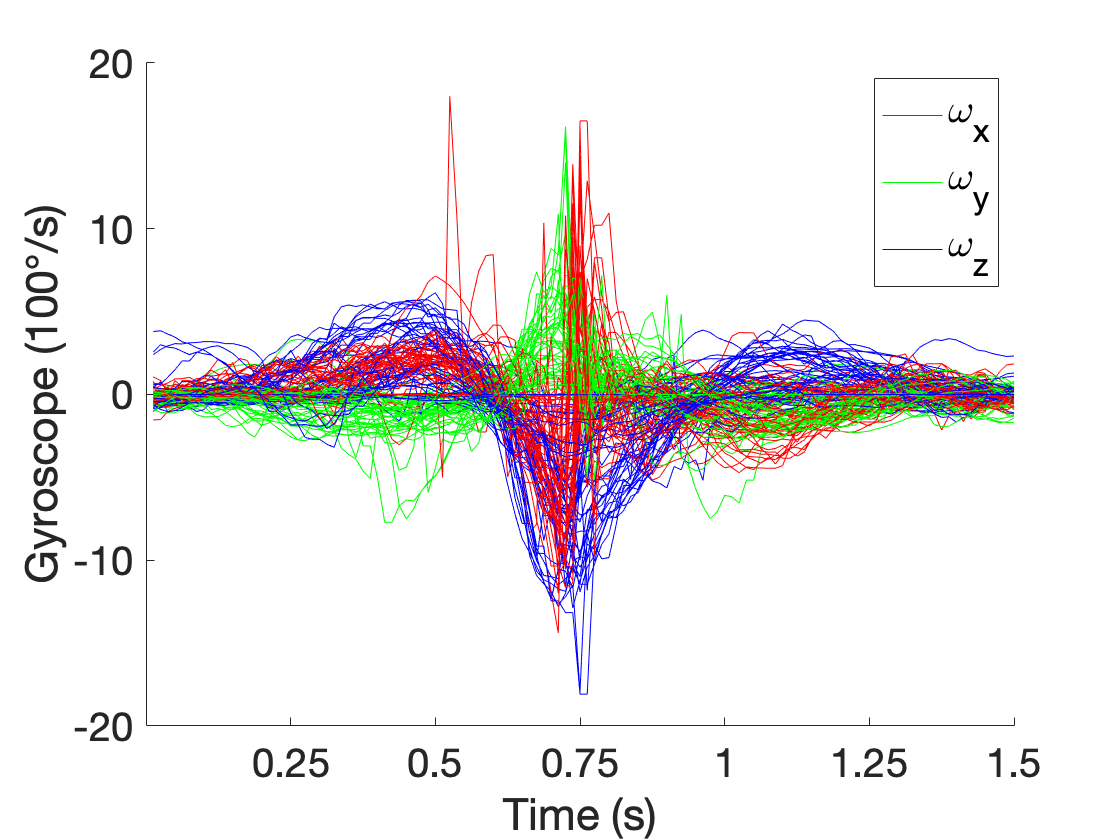

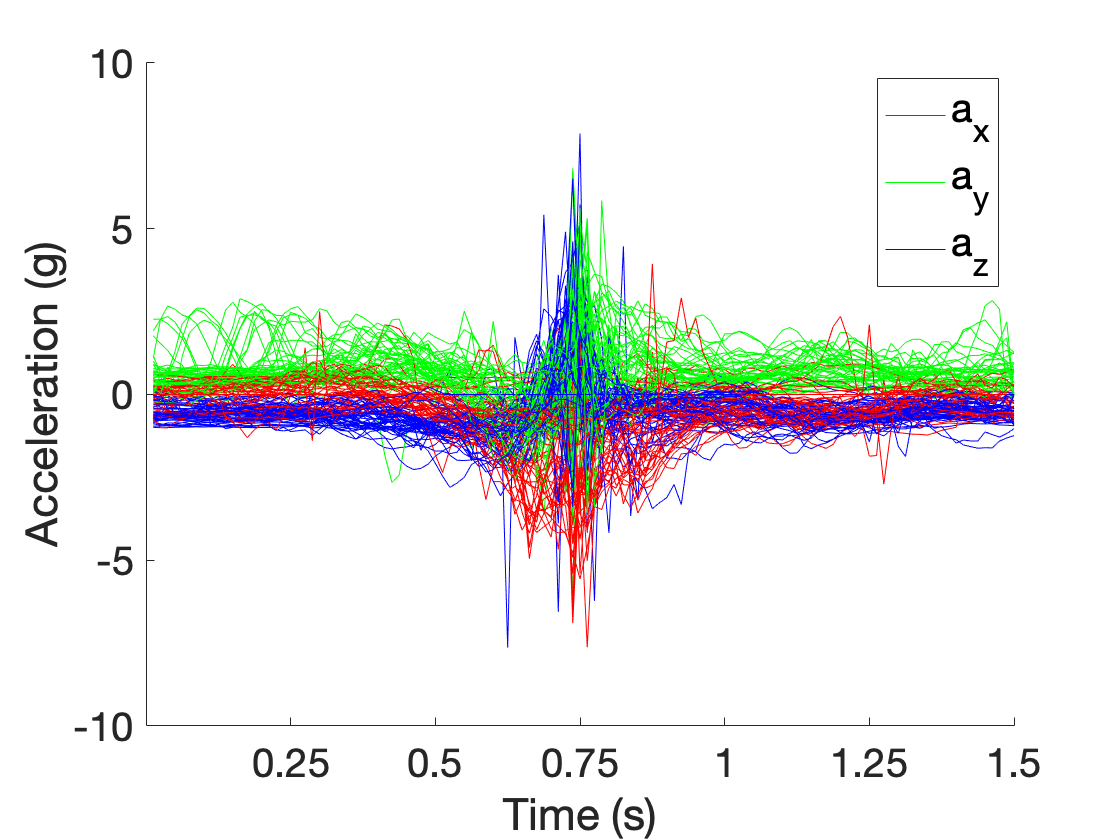

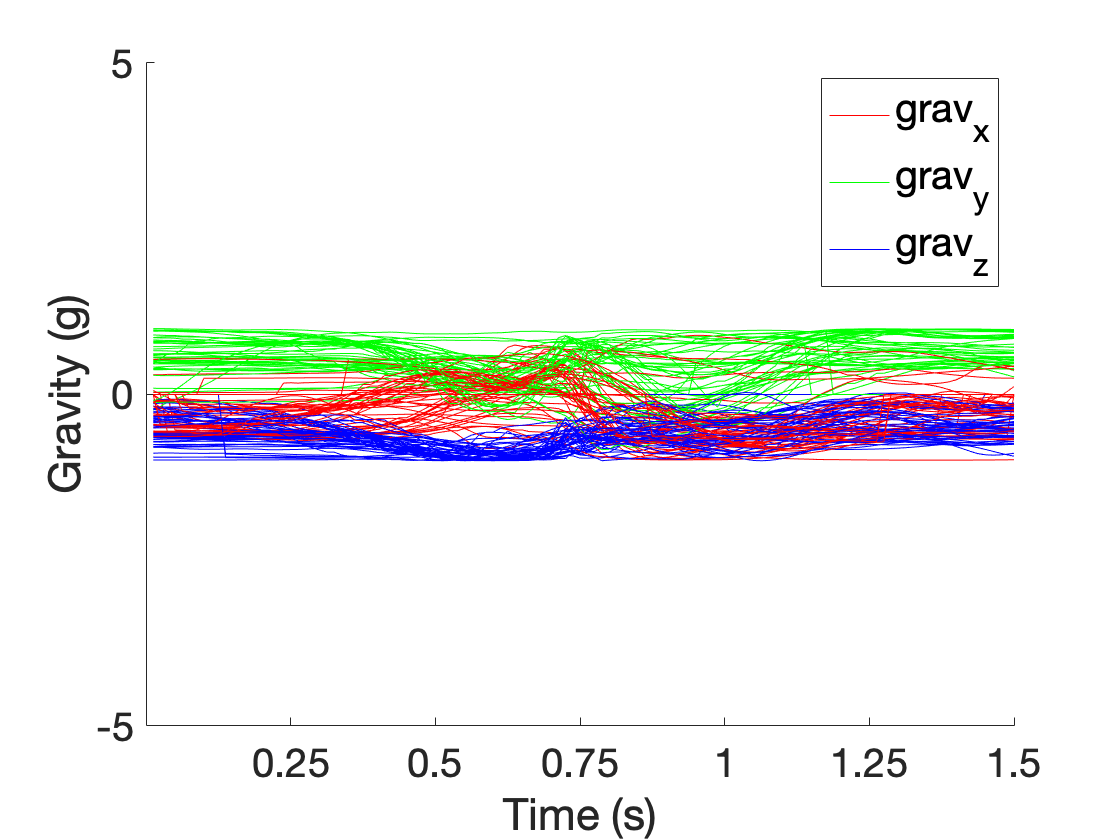

% Change variable names
Filename56 = string(Path) + 'Player 23/M.Me.BdV.23.1.csv';
Filename57 = string(Path) + 'Player 23/M.Me.BdV.23.2.csv';
Filename58 = string(Path) + 'Player 24/F.E.BdV.24.csv';
Filename61 = string(Path) + 'Player 25/F.E.BdV.25.csv';
Filename59 = string(Path) + 'Player 21/F.B.BdV.21.1.csv';
Filename60 = string(Path) + 'Player 21/F.B.BdV.21.2.csv';
Filename62 = string(Path) + 'Player 26/F.B.BdV.26.1.csv';
Filename63 = string(Path) + 'Player 26/F.B.BdV.26.2.csv';
Filename64 = string(Path) + 'Player 27/F.B.BdV.27.1.csv';
Filename65 = string(Path) + 'Player 27/F.B.BdV.27.2.csv';
Filename66 = string(Path) + 'Player 24/F.E.BdV.24.csv';
Filename67 = string(Path) + 'Player 25/F.E.BdV.25.csv';

files_bv = [Filename56, Filename57, Filename58, Filename67,Filename60,Filename61,Filename62,Filename63,Filename64,Filename65,Filename66,Filename59];

[AllbvGyroX,AllbvGyroY,AllbvGyroZ,AllbvAccelX,AllbvAccelY,AllbvAccelZ,AllbvGravX,AllbvGravY,AllbvGravZ] = Compile_trial(files_bv, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[bvaMax,bvaMin,bvaMean,bvaStd,bvaArea,bvgMax,bvgMin,bvgMean,bvgStd,bvgArea,bvgravMax,bvgravMin,bvgravMean,bvgravStd,bvgravArea] = MaxMin_trial(AllbvGyroX,AllbvGyroY,AllbvGyroZ,AllbvAccelX,AllbvAccelY,AllbvAccelZ,AllbvGravX,AllbvGravY,AllbvGravZ);
[RacketSpeedAverage] = RacketSpeed(AllbvGyroY, AllbvGyroZ);

RacketSpeedAverage = 25.4307

## Backhand Volley (Disha's data)

% Filename1= string(Path_Disha) + '00859_CalInertialAndMag.csv';% Disha
% Filename2= string(Path_Disha) + '00862_CalInertialAndMag.csv';% Belen
% 
% files_bv_Disha = [Filename1, Filename2];
% 
% [AllbvDGyroX,AllbvDGyroY,AllbvDGyroZ,AllbvDAccelX,AllbvDAccelY,AllbvDAccelZ] = Compile_trial(files_bv_Disha, 32, colaccX_Disha,colaccY_Disha,colaccZ_Disha,colgyroX_Disha,colgyroY_Disha,colgyroZ_Disha);
% [bvaDMax,bvaDMin,bvaDMean,bvaDStd,bvaDArea,bvgDMax,bvgDMin,bvgDMean,bvgDStd,bvgDArea] = MaxMin_trial(AllbvDGyroX,AllbvDGyroY,AllbvDGyroZ,AllbvDAccelX,AllbvDAccelY,AllbvDAccelZ);
% [RacketSpeedAverage] = RacketSpeed(AllbvDGyroY, AllbvDGyroZ);

## TRAINING DATASET


start_train = 1;
finish_train = 58;
finish_train_b = 58;
finish_train_s = 58;
finish_train_fv = 58;
finish_train_bv = 58;

aMaxAll=vertcat(faMax(start_train:finish_train,:),baMax(start_train:finish_train_b,:),saMax(start_train:finish_train_s,:))

aMaxAll =     0.1620    1.1258         0
    0.5952    2.3798    4.8953
    0.4884    3.0473    4.9472
    0.5916    2.8666    5.2362
    0.1975    2.3967    5.7734
    0.5465    2.7131    7.1197
    0.5144    3.1518    4.8529
    0.5279    2.4549    5.5320
    0.6532    1.5350    6.0659
         0         0         0


aMinAll=vertcat(faMin(start_train:finish_train,:),baMin(start_train:finish_train_b,:),saMin(start_train:finish_train_s,:));
aMeanAll=vertcat(faMean(start_train:finish_train,:),baMean(start_train:finish_train_b,:),saMean(start_train:finish_train_s,:));
aStdAll=vertcat(faStd(start_train:finish_train,:),baStd(start_train:finish_train_b,:),saStd(start_train:finish_train_s,:));
aAreaAll=vertcat(faArea(start_train:finish_train,:),baArea(start_train:finish_train_b,:),saArea(start_train:finish_train_s,:));
gMinAll=vertcat(fgMin(start_train:finish_train,:),bgMin(start_train:finish_train_b,:),sgMin(start_train:finish_train_s,:));
gMaxAll=vertcat(fgMax(start_train:finish_train,:),bgMax(start_train:finish_train_b,:),sgMax(start_train:finish_train_s,:))

gMaxAll =     0.2352    2.6153    0.2026
   11.8581    2.4712    7.4268
   14.5461    3.0527    5.7703
   16.9150    3.5481    7.4835
   15.8440    4.6558    8.8124
   14.5894    3.4151    7.8534
   23.7708    3.6402    6.9930
   18.9060    4.0045    8.8275
   19.4705    3.4759    9.0966
         0         0         0


gMeanAll=vertcat(fgMean(start_train:finish_train,:),bgMean(start_train:finish_train_b,:),sgMean(start_train:finish_train_s,:));
gStdAll=vertcat(fgStd(start_train:finish_train,:),bgStd(start_train:finish_train_b,:),sgStd(start_train:finish_train_s,:));
gAreaAll=vertcat(fgArea(start_train:finish_train,:),bgArea(start_train:finish_train_b,:),sgArea(start_train:finish_train_s,:));


Class(1:finish_train,1)=1; 
Class(finish_train+1:finish_train+finish_train_b,1)=2; 
Class(finish_train+finish_train_b+1:finish_train+finish_train_b+finish_train_s,1)=3; 

fullArray=horzcat(aMaxAll,aMinAll,aMeanAll,aStdAll,aAreaAll,gMaxAll,gMinAll,gMeanAll,gStdAll,gAreaAll,Class);
%normalize/standardize all elements in the array
means=mean(fullArray);
stds=std(fullArray);
normfullArray = zeros(size(fullArray,1),size(fullArray,2)-1);
for i=1:size(fullArray,2)-1
    normfullArray(:,i)=(fullArray(:,i)-means(1,i))/stds(1,i);
end

normfullArray2=horzcat(normfullArray,Class);
colNames={'aXmax','aYmax','aZmax','aXmin','aYmin','aZmin','aXmean','aYmean','aZmean','aXstd','aYstd','aZstd','aXArea','aYArea','aZArea','gXmax','gYmax','gZmax','gXmin','gYmin','gZmin','gXmean','gYmean','gZmean','gXstd','gYstd','gZstd','gXArea','gYArea','gZArea','Class'};
completeTable=array2table(fullArray,'VariableNames',colNames)

completeTable = 174×31 table
     aXmax     aYmax      aZmax      aXmin        aYmin       aZmin       aXmean     aYmean       aZmean        aXstd      aYstd      aZstd     aXArea     aYArea     aZArea      gXmax      gYmax      gZmax      gXmin      gYmin       gZmin      gXmean      gYmean       gZmean      gXstd      gYstd      gZstd     gXArea     gYArea     gZArea     Class
    _______    ______    _______    

## TESTING DATASET

t_1 = zeros(15,1);
t_1(1:5,1)=1; %forehand 
t_1(6:10,1)=2; %backhand 
t_1(11:15,1)=3; %serve 

f_start = finish_train+1;
f_finish = 63;
b_start = finish_train_b+1;
b_finish = 63;
s_start = finish_train_s+1;
s_finish = 63;
fv_start = finish_train_fv+1;
fv_finish = 63;
bv_start = finish_train_bv+1;
bv_finish = 63;


aMaxAll=vertcat(faMax(f_start:f_finish,:),baMax(b_start:b_finish,:),saMax(s_start:s_finish,:));
aMinAll=vertcat(faMin(f_start:f_finish,:),baMin(b_start:b_finish,:),saMin(s_start:s_finish,:));
aMeanAll=vertcat(faMean(f_start:f_finish,:),baMean(b_start:b_finish,:),saMean(s_start:s_finish,:));
aStdAll=vertcat(faStd(f_start:f_finish,:),baStd(b_start:b_finish,:),saStd(s_start:s_finish,:));
aAreaAll=vertcat(faArea(f_start:f_finish,:),baArea(b_start:b_finish,:),saArea(s_start:s_finish,:));
gMinAll=vertcat(fgMin(f_start:f_finish,:),bgMin(b_start:b_finish,:),sgMin(s_start:s_finish,:));
gMaxAll=vertcat(fgMax(f_start:f_finish,:),bgMax(b_start:b_finish,:),sgMax(s_start:s_finish,:));
gMeanAll=vertcat(fgMean(f_start:f_finish,:),bgMean(b_start:b_finish,:),sgMean(s_start:s_finish,:));
gStdAll=vertcat(fgStd(f_start:f_finish,:),bgStd(b_start:b_finish,:),sgStd(s_start:s_finish,:));
gAreaAll=vertcat(fgArea(f_start:f_finish,:),bgArea(b_start:b_finish,:),sgArea(s_start:s_finish,:));


fA=horzcat(aMaxAll,aMinAll,aMeanAll,aStdAll,aAreaAll,gMaxAll,gMinAll,gMeanAll,gStdAll,gAreaAll,t_1)

fA =     0.6454    2.3817    2.8485   -3.7057   -1.1289   -1.5559   -0.4389    1.0160    0.2363    0.8645    0.3992    0.8624  -52.8567  120.8939   28.6461    6.5135    3.5201    1.7640   -4.5310  -10.0718   -2.8111   -0.0396   -0.1419   -1.0493    1.4967    3.1162    0.9895   -4.5762  -18.1115 -126.0310    1.0000
    0.7041    2.4043    5.2773   -3.6328   -1.9752   -1.1121   -0.4838    0.7655   -0.0161    0.8064    0.4892    1.0617  -58.0449   91.0930   -1.6850    6.1017    3.3549    1.8074   -5.6570   -9.0540   -3.8367    0.0121   -0.8234   -1.2200    1.5559    2.5102    1.1980    2.0643 -100.4133 -146.3044    1.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000
    0.5648    0.9161         0   -0.3331         0   -1.1251  

% fA=fA(any(fA(:,1:45),2),:)
%Normalise features
mns=mean(fA);
stds=std(fA);
nfA = zeros(size(fA,1),size(fA,2)-1);
for i=1:size(fA,2)-1
    nfA(:,i)=(fA(:,i)-mns(1,i))/stds(1,i);
end
nfA2=horzcat(nfA,t_1);
colNames={'aXmax','aYmax','aZmax','aXmin','aYmin','aZmin','aXmean','aYmean','aZmean','aXstd','aYstd','aZstd','aXArea','aYArea','aZArea','gXmax','gYmax','gZmax','gXmin','gYmin','gZmin','gXmean','gYmean','gZmean','gXstd','gYstd','gZstd','gXArea','gYArea','gZArea','Class'};
checkTable=array2table(fA,'VariableNames',colNames)

checkTable = 15×31 table
     aXmax      aYmax     aZmax      aXmin       aYmin       aZmin      aXmean     aYmean      aZmean       aXstd      aYstd      aZstd     aXArea     aYArea    aZArea     gXmax     gYmax      gZmax      gXmin      gYmin       gZmin       gXmean       gYmean      gZmean       gXstd      gYstd      gZstd     gXArea     gYArea     gZArea     Class
    _______    _______    ______    _____

checkTable2=checkTable(:,1:30)

checkTable2 = 15×30 table
     aXmax      aYmax     aZmax      aXmin       aYmin       aZmin      aXmean     aYmean      aZmean       aXstd      aYstd      aZstd     aXArea     aYArea    aZArea     gXmax     gYmax      gZmax      gXmin      gYmin       gZmin       gXmean       gYmean      gZmean       gXstd      gYstd      gZstd     gXArea     gYArea     gZArea 
    _______    _______    ______    ________    _

% load W_KNN.mat
yfit = zeros(25,1);
yfit = Fine_KNN.predictFcn(checkTable2) 

yfit =      1
     1
     1
     1
     1
     2
     2
     2
     2
     2


diff=t_1-yfit;
count=nnz(diff);
Accu=1-(count/length(t_1))

Accu = 1

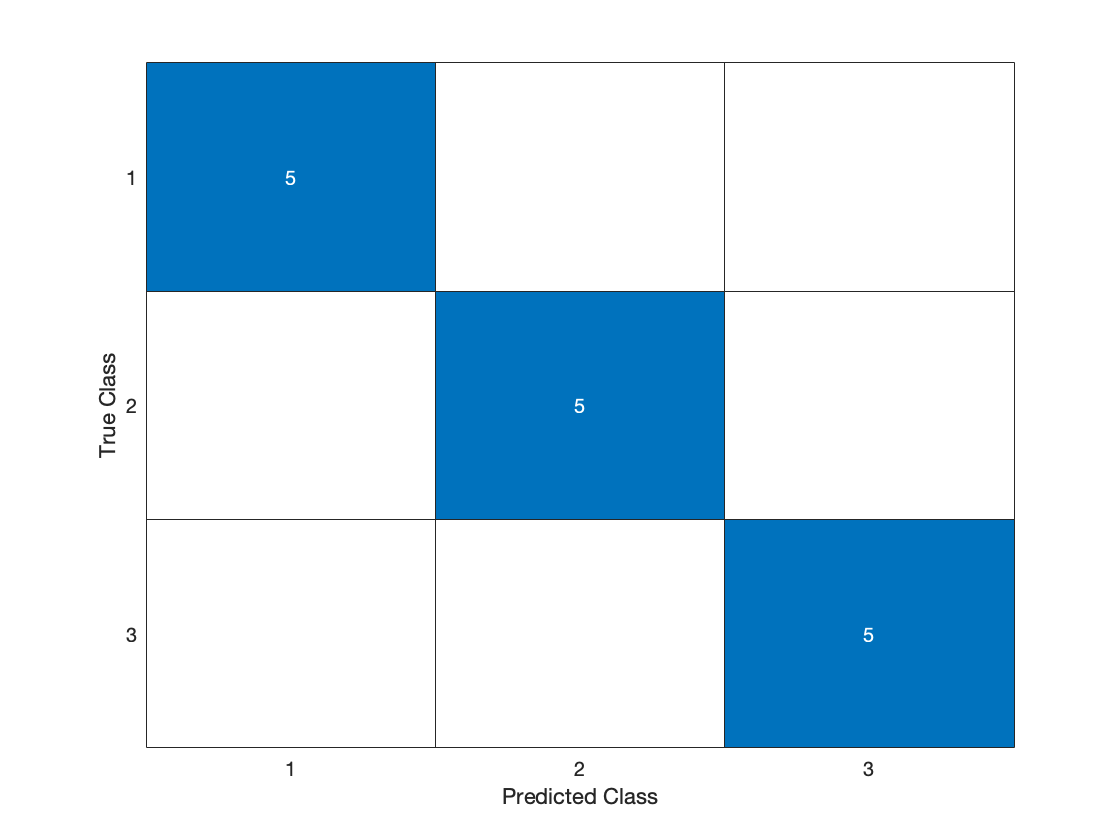

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


cm = confusionchart(t_1,yfit) %confusion matrix on testing data

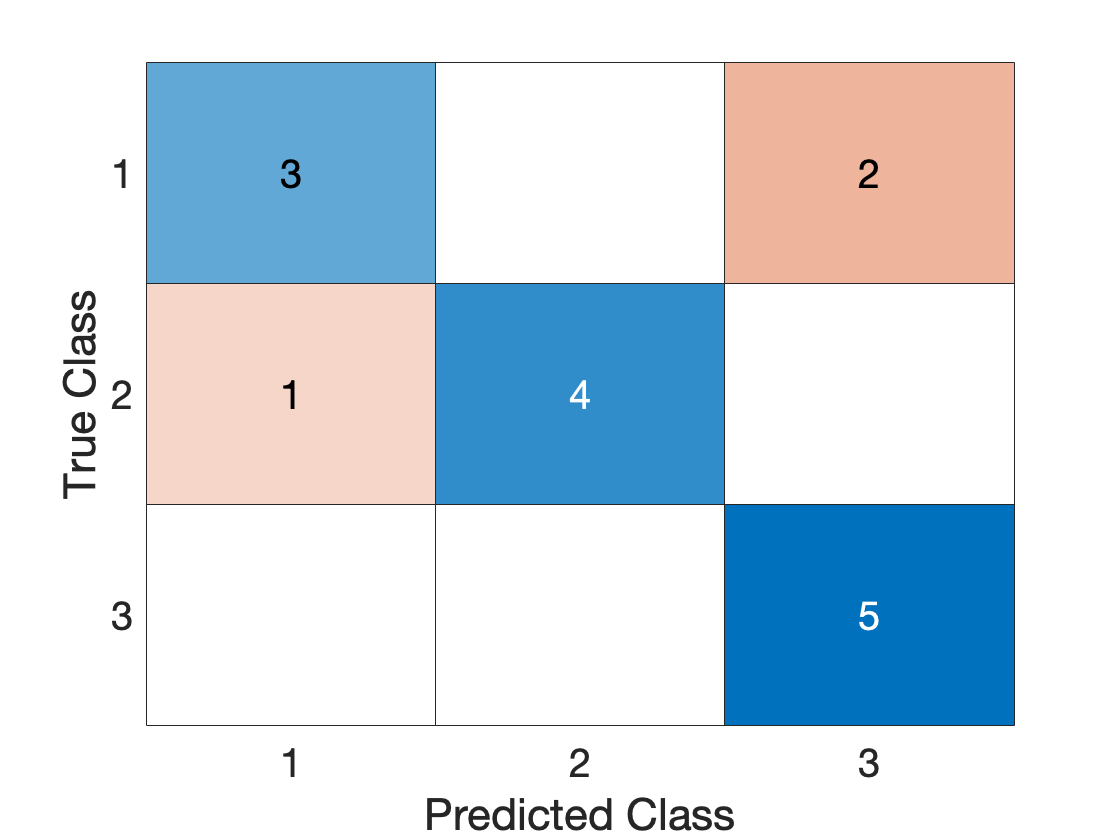

t_2 = zeros(15,1);
t_2(1:5,1) = 1;
t_2(6:10,1) = 2;
t_2(11:15,1) = 3;
% % % 

yfit_2 = zeros(15,1);
yfit_2(1:3,1) = 1;
yfit_2(4:5,1) = 3;
yfit_2(6:9,1) = 2;
yfit_2(10:10,1) = 1;
yfit_2(11:15,1) = 3;

confusionchart(t_2,yfit_2, 'FontSize',20) %confusion matrix on testing data

%3d plot 
% figure
% scatter3(fgMin(:,2),fgMean(:,3),fgravArea(:,1))
% hold on
% scatter3(bgMin(:,2),bgMean(:,3),bgravArea(:,1))
% scatter3(sgMin(:,2),sgMean(:,3),sgravArea(:,1))
% scatter3(fvgMin(:,2),fvgMean(:,3),fvgravArea(:,1))
% scatter3(bvgMin(:,2),bvgMean(:,3),bvgravArea(:,1))
% xlabel('\omega_{min,y} (100deg/s)','FontSize', 20); %x-axis label 
% legend('Forehand', 'Backhand',  'Serve', 'Forehand Volley', 'Backhand Volley', 'FontSize', 18)
% ylabel('\omega_{ave,z} (100deg/s)','FontSize', 18); %y-axis label
% zlabel('grav_{area,x} (g)','FontSize', 18); %y-axis label
% set(gca,'FontSize',18)
% hold off
% hold off
